Settle = datetime(2024,3,22);
SpotPrice = 170.86;
Rate = 0.0549;
MaturityDates = datetime([2024,4,19;2024,5,17;2024,6,21]);
Strikes=K;
prices=call;
ZeroCurve=  ratecurve("zero", Settle, MaturityDates(end), Rate)

ZeroCurve =   ratecurve - 属性:

                 Type: "zero"
          Compounding: -1
                Basis: 0
                Dates: 2024-06-21
                Rates: 0.0549
               Settle: 2024-03-22
         InterpMethod: "linear"
    ShortExtrapMethod: "next"
     LongExtrapMethod: "previous"


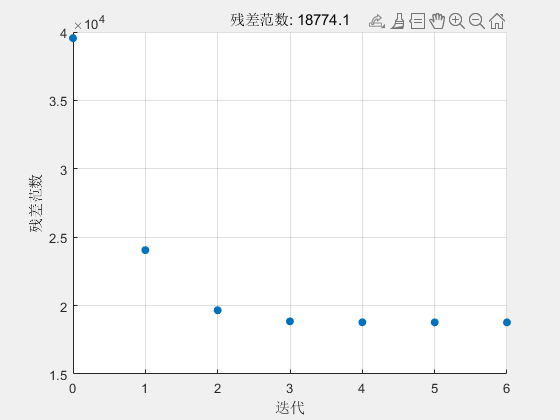


可能存在局部最小值。

lsqnonlin 已停止，因为平方和相对于其初始值的最终变化小于函数容差值。

<停止条件详细信息>



% Create fininstrument objects
[MAT, STR] = meshgrid(MaturityDates', Strikes);
Inst = fininstrument('Vanilla', 'ExerciseDate', MAT(:), ...
	'Strike', STR(:), 'OptionType', 'Call');

% Construct objective function
objectiveFcn = @(Param) prices(:) - price(finpricer('FFT', 'Model', ...
	finmodel('Heston', 'V0', Param(1), 'ThetaV', Param(2), ...
	'Kappa', Param(3), 'SigmaV', Param(4), 'RhoSV', Param(5)), ...
	'SpotPrice', 123.28, 'DiscountCurve', ZeroCurve), Inst);

% Estimate model parameters
options = optimoptions('lsqnonlin', 'FunctionTolerance', 0.0001, ...
	'Display', 'final', 'PlotFcn', 'optimplotresnorm');
Param = lsqnonlin(objectiveFcn, [0.1 0.4 0.2 0.6 -0.1], [0 0 0 0 -1], ...
	[1 1 10 2 1], options);


HestonModel = finmodel('Heston', 'V0', Param(1), 'ThetaV', Param(2), ...
	'Kappa', Param(3), 'SigmaV', Param(4), 'RhoSV', Param(5))

HestonModel =   Heston - 属性:

        V0: 1.0000
    ThetaV: 1.0000
     Kappa: 3.3626e-04
    SigmaV: 0.2301
     RhoSV: -1.0000


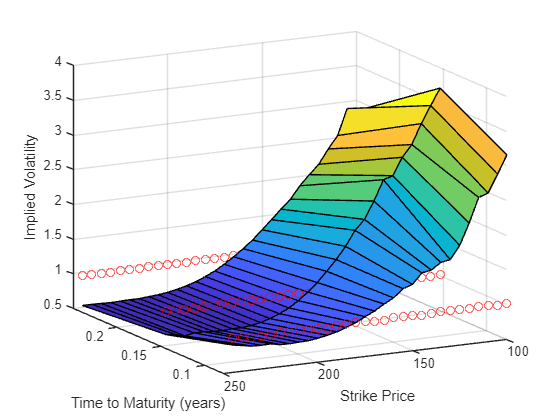


% Calculate implied volatilities for market and model prices
TMAT = yearfrac(ZeroCurve.Settle, MAT);
MKTVOL = blsimpv(123.28, STR, ZeroCurve.Rates(1), TMAT, prices);

ModelPrice = price(finpricer('FFT', 'Model', HestonModel, 'SpotPrice', 123.28, ...
	'DiscountCurve', ZeroCurve), Inst);
ModelVol = blsimpv(123.28, STR(:), ZeroCurve.Rates(1), TMAT(:), ModelPrice);

% Plot implied volatility surface
figure
surf(TMAT, STR, MKTVOL)
hold on
scatter3(TMAT(:), STR(:), ModelVol, 'ro')
xlabel('Time to Maturity (years)')
ylabel('Strike Price')
zlabel('Implied Volatility')
hold off
grid on